**Introduction**

This document is to explore the waveform of OTFS in ***fractional Dopplers*** for ***ideal pulses***. 

**Basic settings**

clear;
clc;
N = 15;                          % time slot number
M = 4;                         % subcarrier number
% x
x_value = 1+1j;
x_delay_pos = [1, 2];
x_doppl_pos = 8*ones(length(x_delay_pos), 1);
x_num = length(x_delay_pos);
x = zeros(N, M);    
for x_id = 1:x_num
    x(x_doppl_pos(x_id), x_delay_pos(x_id)) = x_value;
end
% channel
hi = 1;
li = 0;
ki = 1.2;
kv = 4;
cp_len = 4

cp_len = 4

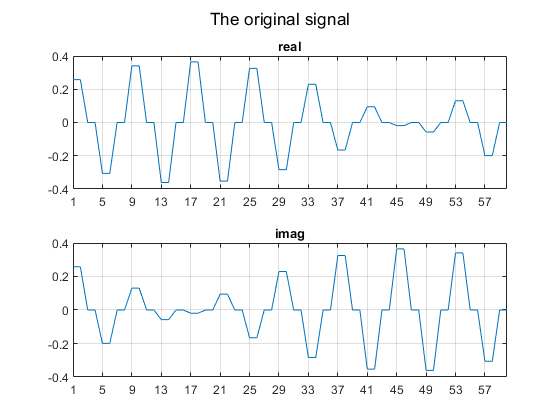

% modulation
s = OTFS_modulation(N,M,x);
plot_s(s, M, N);

% add cp
s_cp = [s(N*M-cp_len+1:N*M);s];

**Case 1: Emanuele Viterbo Channel in time domain**

We pass the signal through the channel first.

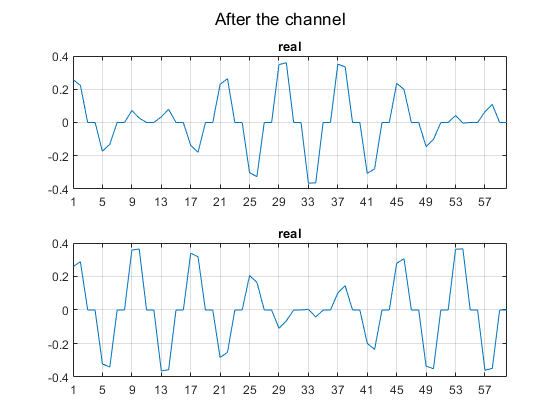

% pass the channel
case2_s_chan_0delay = hi*[s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)];
case2_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case2_r = case2_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case2_r, M, N);

% to Rx DD domain
case2_y = OTFS_demodulation(N,M,case2_r);
R = reshape(case2_r, M, N);
R = R.';
Y = fft(R)/sqrt(N);
% calculate the value on
Y(:, 3) = Y(:, 2)/exp(2j*pi*ki*1/M/N); 
Y(:, 4) = abs(Y(:, 3) - Y(:, 1));

If you look at $y$, you will realize that the channe is the same for different channel.

**Functions**

function plot_s(s, M, N)
    figure("name", "The original signal")
    subplot(2,1,1)
    plot(real(s));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(s));
    title("imag");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("The original signal")
end
function plot_r(r, M, N)
    figure("name", "Time domain")
    subplot(2,1,1)
    plot(real(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("After the channel")
end
